Numerical solving of the differential equation. Pourpose is to confirm simscape model, with "hand-claculations"

Damping coefficient is estimated, and simulink simulation is set with a fixed timestep.

close all;

Loading and saving data from simulink:

%thetaSim = out.simout;
%tSim = out.tout;
%simTable = array2table(tSim);
%simTable.thetaSim = thetaSim;
%writetable(simTable, "simData.xlsx")
%save("simTable.mat", "simTable")


Parameters for the numerical solutions

kd = 0.001; % [Nm]/[rad/s] damping coefficient
mLongRod = 28.27/1000; % [kg]
g = 9.81; 
L = 250/1000 % [m]

L =    0.250000000000000


Calculating inertias:

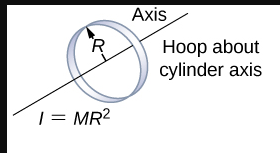

I_shortRod = (19.79/1000)*(4.5/1000)^2 % [kg*m^2]

I_shortRod =      4.007474999999999e-07


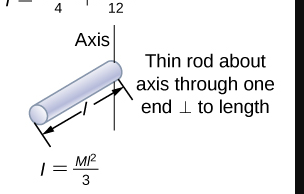

I_longRod = (((28.27/1000)*0.5^2)/3) + (28.27/1000)*(5/1000)^2 % [kg*m^2]

I_longRod =    0.002356540083333


I_link = (9.92/1000) * ((35/2)/1000)^2 % [kg*m^2] estimated

I_link =      3.038000000000000e-06


I_total = I_shortRod + I_longRod + I_link

I_total =    0.002359978830833


The function:

thetaDotDot = @(theta, thetaDot) (-cos(theta)*mLongRod*g*L - kd*thetaDot)/(I_total)

thetaDotDot = function_handle with value:
    @(theta,thetaDot)(-cos(theta)*mLongRod*g*L-kd*thetaDot)/(I_total)


The initial conditions:

thetaDotDot_0 = 0;
thetaDot_0 = 0;
theta_0(1:1501) = 0; % 1:1501 to allocate memory befor the loop

Simulation parametes:

stepSize = 0.01; % delt t [s]
endValue = 15; % [s]
k = 1;
for i = [0:stepSize:endValue]
    thetaDotDot_0 = thetaDotDot(theta_0(k), thetaDot_0);
    thetaDot_0 = thetaDot_0 + thetaDotDot_0*stepSize;
    theta_0(k+1) = theta_0(k) + thetaDot_0*stepSize;
    k = k + 1;
end

Plotting the numeric angle vs time:

tNumeric = [0:stepSize:15];
theta_0(end) = [];
plot(tNumeric, theta_0)
hold on;


Plotting the simulated angle vs time:

load("model_verification\simTable.mat");
plot(simTable.tSim, simTable.thetaSim)

Fixing the plot:

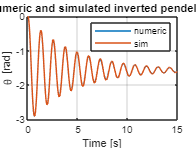

legend("numeric", "sim")
grid on;
box on;
title("Numeric and simulated inverted pendelium");
ylabel("\theta [rad]");
xlabel("Time [s]")